# Locally Weighted Scatterplot Smoothing

A program which is developed based on lowess approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


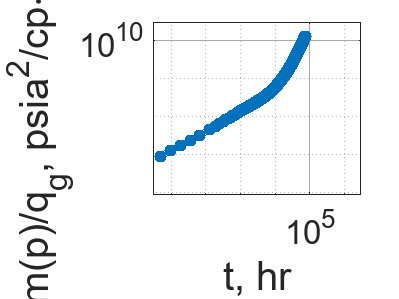


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 202

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_202 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\75%\noisy_data_2.txt", opts)

noisy_RNP_202 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.5482e+08
    0.33041    2.4207e+08
     0.4862    5.6497e+07
    0.79777    1.0336e+07
     1.4209    1.7383e+08
     2.6672    1.5154e+08
     5.0773    1.0631e+08
     9.8974     9.008e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    7.4037e+07
     124.99    2.3439e+08
     188.99    5.4925e+07
     252.99    1.4538e+08
     316.99    1.2064e+08
     380.99    1.6553e+08


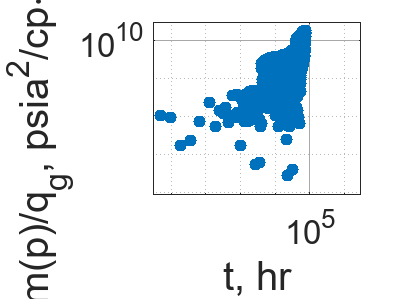


% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 202

logRNP_202 = log(noisy_RNP_202.RNP);

#### Window: 3

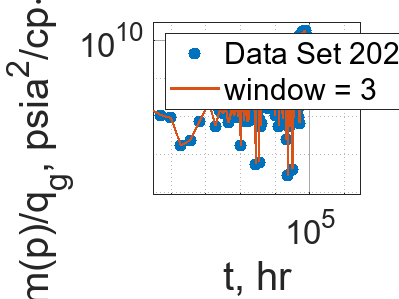

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_31 = smooth(logRNP_202, 3, "lowess");
smoothedRNP_202_31 = exp(smoothedLogRNP_202_31);
residual_202_31 = (true_RNP.RNP - smoothedRNP_202_31) ./ (0.3413 .* true_RNP.RNP);
sse_202_31 = sum(residual_202_31 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3");
legend("Location", "northwest");
hold off;

### Window: 5

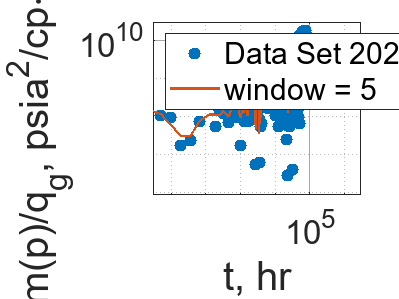

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_51 = smooth(logRNP_202, 5, "lowess");
smoothedRNP_202_51 = exp(smoothedLogRNP_202_51);
residual_202_51 = (true_RNP.RNP - smoothedRNP_202_51) ./ (0.3413 .* true_RNP.RNP);
sse_202_51 = sum(residual_202_51 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5");
legend("Location", "northwest");
hold off;

#### Window: 7

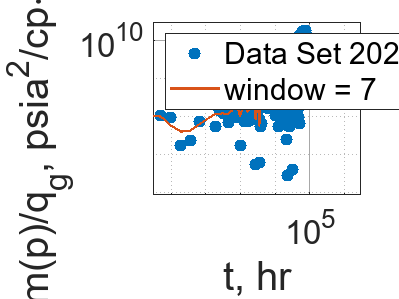

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_71 = smooth(logRNP_202, 7, "lowess");
smoothedRNP_202_71 = exp(smoothedLogRNP_202_71);
residual_202_71 = (true_RNP.RNP - smoothedRNP_202_71) ./ (0.3413 .* true_RNP.RNP);
sse_202_71 = sum(residual_202_71 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7");
legend("Location", "northwest");
hold off;

#### Window: 9

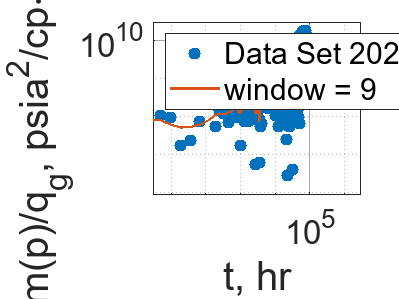

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_91 = smooth(logRNP_202, 9, "lowess");
smoothedRNP_202_91 = exp(smoothedLogRNP_202_91);
residual_202_91 = (true_RNP.RNP - smoothedRNP_202_91) ./ (0.3413 .* true_RNP.RNP);
sse_202_91 = sum(residual_202_91 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9");
legend("Location", "northwest");
hold off;

#### Window: 11

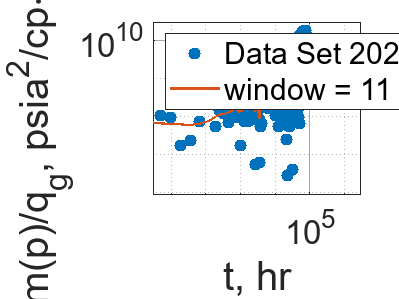

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_111 = smooth(logRNP_202, 11, "lowess");
smoothedRNP_202_111 = exp(smoothedLogRNP_202_111);
residual_202_111 = (true_RNP.RNP - smoothedRNP_202_111) ./ (0.3413 .* true_RNP.RNP);
sse_202_111 = sum(residual_202_111 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11");
legend("Location", "northwest");
hold off;

#### Window: 13

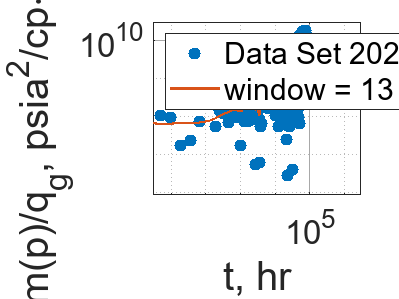

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_131 = smooth(logRNP_202, 13, "lowess");
smoothedRNP_202_131 = exp(smoothedLogRNP_202_131);
residual_202_131 = (true_RNP.RNP - smoothedRNP_202_131) ./ (0.3413 .* true_RNP.RNP);
sse_202_131 = sum(residual_202_131 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_131, "-", "LineWidth", 1.3, "DisplayName", "window = 13");
legend("Location", "northwest");
hold off;

#### Window: 15

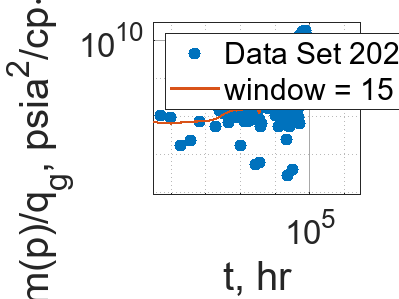

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_151 = smooth(logRNP_202, 15, "lowess");
smoothedRNP_202_151 = exp(smoothedLogRNP_202_151);
residual_202_151 = (true_RNP.RNP - smoothedRNP_202_151) ./ (0.3413 .* true_RNP.RNP);
sse_202_151 = sum(residual_202_151 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_151, "-", "LineWidth", 1.3, "DisplayName", "window = 15");
legend("Location", "northwest");
hold off;

#### Window: 17

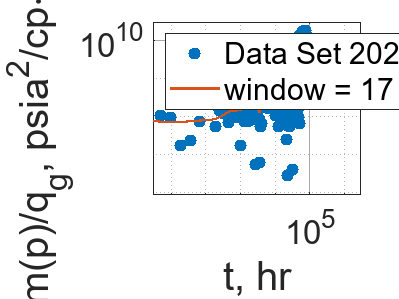

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_171 = smooth(logRNP_202, 17, "lowess");
smoothedRNP_202_171 = exp(smoothedLogRNP_202_171);
residual_202_171 = (true_RNP.RNP - smoothedRNP_202_171) ./ (0.3413 .* true_RNP.RNP);
sse_202_171 = sum(residual_202_171 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_171, "-", "LineWidth", 1.3, "DisplayName", "window = 17");
legend("Location", "northwest");
hold off;

#### Window: 19

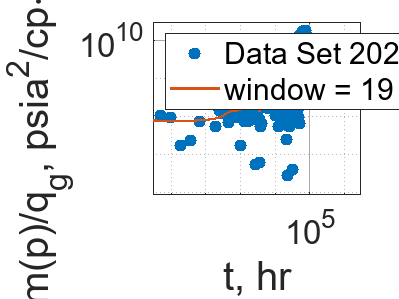

% Plot
loglog(noisy_RNP_202.t, noisy_RNP_202.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 202");
% title("Noisy RNP Data Set 202", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_202_202 = smooth(logRNP_202, 19, "lowess");
smoothedRNP_202_202 = exp(smoothedLogRNP_202_202);
residual_202_202 = (true_RNP.RNP - smoothedRNP_202_202) ./ (0.3413 .* true_RNP.RNP);
sse_202_202 = sum(residual_202_202 .^ 2);
loglog(noisy_RNP_202.t, smoothedRNP_202_202, "-", "LineWidth", 1.3, "DisplayName", "window = 19");
legend("Location", "northwest");
hold off;